# Practical 5

# Name : Varun Khadayate

# Roll No. : A016

## Basic Plotting-2D and 3D 

## Part A: Theory

plot3 - plots curves in space,

stem3 - creates discrete data plot with stems in 3-D,

bar3 - plots 3-D bar graph,

bar3h - plots 3-D horizontal bar graph,

pie3 - makes 3-D pie chart,

comet3 - makes animated 3-D line plot,

fill3 - draws filled 3-D polygons,

contour3 - makes 3-D contour plots,

quivers - draws vector fields in 3-D,

scatter3 - makes scatter plots in 3-D,

mesh - draws 3-D mesh surfaces (wire-frame),

meshc - draws 3-D mesh surfaces along with contours,

meshz - draws 3-D mesh surfaces with reference plane curtains,

surf - creates 3-D surface plots,

surfc - creates 3-D surface plots along with contours,

surfl - creates 3-D surface plots with specified light source,

trimesh - mesh plot with triangles,

trisurf - surface plot with triangles,

slice - draws a volumetric surface with slices,

waterfall - creates a waterfall plot of 3-D data,

cylinder - generates a cylinder,

ellipsoid - generates an ellipsoid, and

sphere - generates a sphere.

### plot3

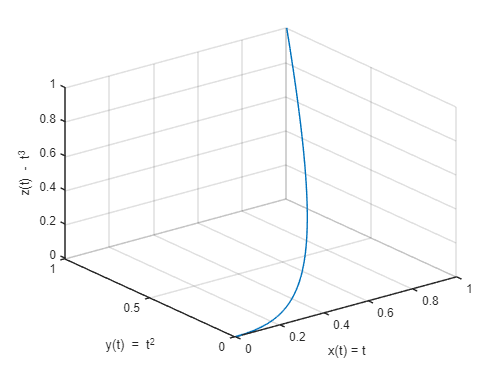

t = linspace (0, 1, 100);
x = t; y = t.^ 2; z = t.^ 3;
plot3(x, y,z), grid
xlabel ('x(t) = t' )
ylabel ('y(t) = t^2')
zlabel ('z(t) - t^3')

### fill3

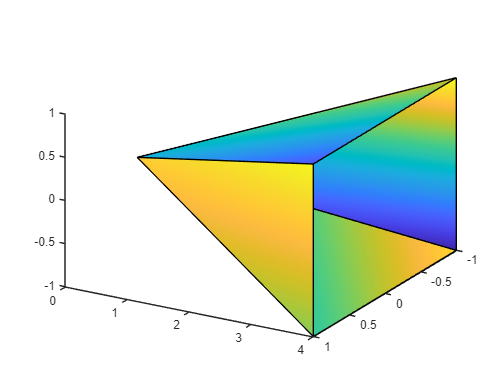

X = [0 0 0 0; 1 1 -1 1;1 -1 -1 -1] ;
Y = [0 0 0 0; 4 4 4 4;4 4 4 4] ;
Z = [0 0 0 0; 1 1 -1 -1;-1 1 1 -1];
fillcolor=rand(3,4);
fill3(X,Y,Z,fillcolor)
view(120,30)

### contour3

r = linspace(-3,3,50);
[x,y] = meshgrid(r,r);
z = -5./(1+ x.^2 + y.^2)

z =    -0.2632   -0.2735   -0.2842   -0.2953   -0.3067   -0.3184   -0.3304   -0.3427   -0.3551   -0.3676   -0.3802   -0.3927   -0.4051   -0.4173   -0.4291   -0.4404   -0.4511   -0.4611   -0.4702   -0.4783   -0.4853   -0.4910   -0.4954   -0.4983   -0.4998   -0.4998   -0.4983   -0.4954   -0.4910   -0.4853   -0.4783   -0.4702   -0.4611   -0.4511   -0.4404   -0.4291   -0.4173   -0.4051   -0.3927   -0.3802   -0.3676   -0.3551   -0.3427   -0.3304   -0.3184   -0.3067   -0.2953   -0.2842   -0.2735   -0.2632
   -0.2735   -0.2847   -0.2964   -0.3084   -0.3209   -0.3337   -0.3469   -0.3604   -0.3742   -0.3881   -0.4022   -0.4162   -0.4302   -0.4439   -0.4573   -0.4702   -0.4825   -0.4939   -0.5043   -0.5137   -0.5217   -0.5283   -0.5334   -0.5368   -0.5386   -0.5386   -0.5368   -0.5334   -0.5283   -0.5217   -0.5137   -0.5043   -0.4939   -0.4825   -0.4702   -0.4573   -0.4439   -0.4302   -0.4162   -0.4022   -0.3881   -0.3742   -0.3604   -0.3469   -0.3337   -0.3209   -0.3084   -0.2964   -0.2847   -0

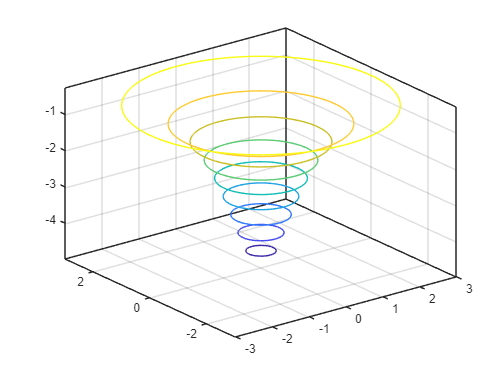

contour3(x,y,z)

### surf

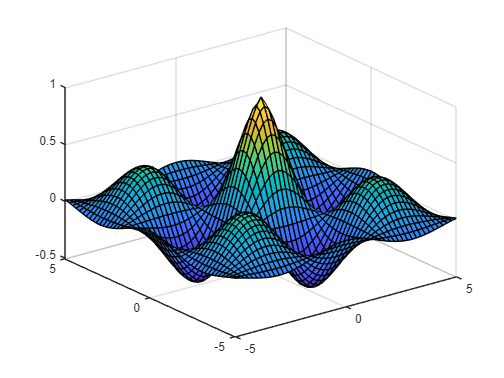

u = -5:.2:5;
[X,Y] = meshgrid(u,u);
Z = cos(X) .* cos(Y) .* exp(-sqrt(X.^2+ Y.^2)/4);
surf(X,Y,Z)

### surfc

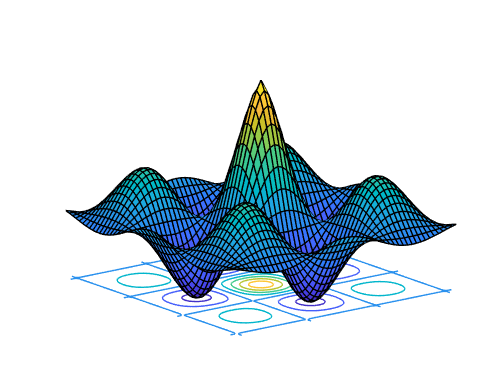

u = -5:.2:5;
[X,Y] = meshgrid(u,u);
Z = cos(X) .* cos(Y) .* exp(-sqrt(X.^2+ Y.^2)/4);
surfc(Z)
view(-37.5,20)
axis('off')

### surfl

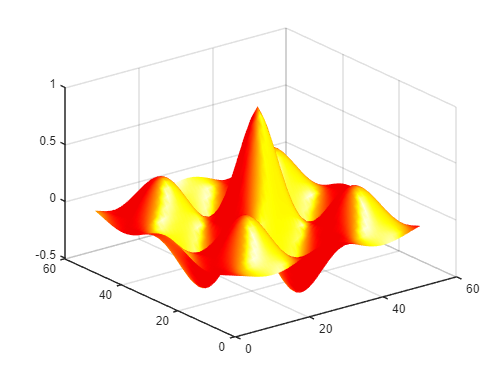

u = -5:.2:5;
[X,Y] = meshgrid(u,u);
z = cos(X) .* cos(Y) .* exp(-sqrt(X.^2+ Y.^2)/4);
surfl(Z)
shading interp
colormap hot

## Part B: Practical

1. Plot voltage vs time for various RC time constants


$$\frac{\upsilon }{V}=e^{-\frac{t}{\tau }}$$


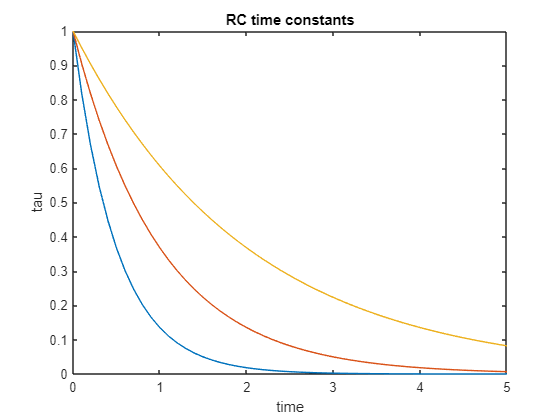

time = 0:0.1:5;
tau = [0.5 1.0 2.0];
[TIME TAU] = meshgrid(time,tau);
V = exp(-TIME./TAU);
plot(time,V)
xlabel('time')
ylabel('tau')
title('RC time constants')

2. Plot a sphere, which is defined as [x(t, s), y(t, s), z(t, s)] = [cos(t) cos(s), cos(t) sin(s), sin(t)] (use ‘surf’). for t, s = [0, 2$\pi$ ] .Make first equal axes, then remove them. Use ‘shading interp’ to remove black lines.

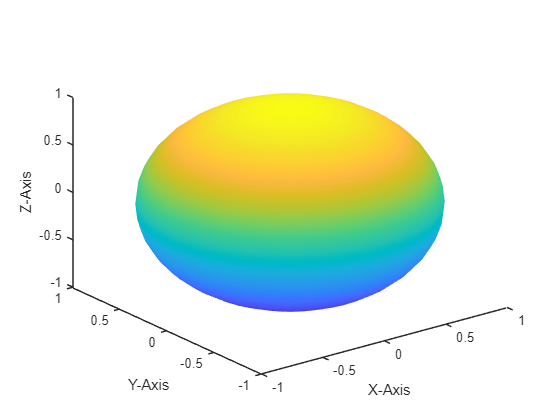

[s,t] = meshgrid(0:0.05*pi:2*pi,0:0.05*pi:2*pi);
x = cos(t) .* cos(s);
y = cos(t) .* sin(s);
z = sin(t);
surf(x,y,z)
xlabel('X-Axis')
ylabel('Y-Axis')
zlabel('Z-Axis')
grid off
shading interp